%新方法-分区域拟合  实验2

%标定
squareSize = 20;
imageFileName={'C:\Users\12630\Documents\MATLAB\Examples\R2023a\visionhdl\ImageUndistortHDLExample\IUInput.PNG'}

imageFileName = 1×1 cell 数组
    {'C:\Users\12630\Documents\MATLAB\Examples\R2023a\visionhdl\ImageUndistortHDLExample\IUInput.PNG'}


% Detect calibration pattern in images
[imagePoints, boardSize] = detectCheckerboardPoints(imageFileName);

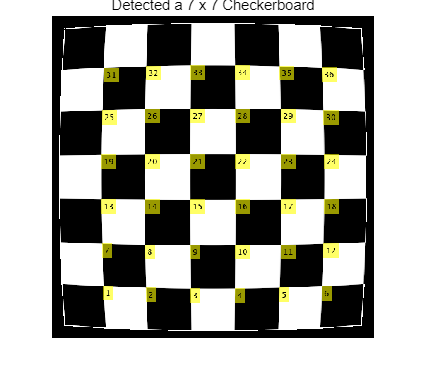

%展示图片及检测出的角点
i=1;
I=imread(imageFileName{i});
J = insertText(I,imagePoints(:,:,i),1:size(imagePoints(:,:,i),1));
% J = insertMarker(J,imagePoints,'o','MarkerColor','red','Size',5);
imshow(J);
title(sprintf('Detected a %d x %d Checkerboard',boardSize));

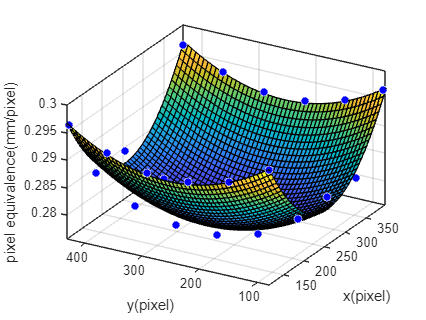

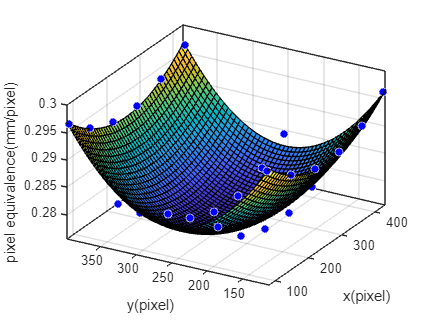

%计算像素当量分布，并用二次曲面拟合
ft = 'poly22';
opts = fitoptions;
[sftx,sfty]=calculate_sft(imageFileName,squareSize,ft = ft,opts = fitoptions);

% 计算原点
% [U,V]=calculate_origin(sftx,sfty);
% origin=[double(U),double(V)];
origin=[255,255];
%计算平均校准精度
NumPatterns=length(imageFileName);
worldPoints = generateCheckerboardPoints(boardSize, squareSize);
error=zeros(length(imagePoints),NumPatterns);
for i=1:NumPatterns
    newWorldPoints= coordinate_transformation(origin,imagePoints(:,:,i),sftx,sfty);
    tform = fitgeotform2d(newWorldPoints,worldPoints,"similarity");
    newWorldPoints=tform.R*newWorldPoints'+tform.Translation';
    newWorldPoints=newWorldPoints';
    for j=1:length(newWorldPoints)
        error(j,i)=norm(worldPoints(j,:)-newWorldPoints(j,:));
    end
end
MeanCalibrationError=mean(error)

MeanCalibrationError = 0.0820

std(error)

ans = 0.0340

im=undistort_image(I,sftx,sfty);
imshowpair(I,im,"montage")